Call the Summary Table

LatexPlots
load SummTableAG

% Delete Analysis for the Last scale factor

filter1 = find(SummTable.hazlvl <= 4);

SummTable_AG = SummTable(filter1, :);

load SummTable_OB_New
filter1 = find(SummTable.hazlvl <= 4);
SummTable_OB = SummTable(filter1, :);

%SummTable_AG

Plot of PGA vs Derailments

%% Collapse this
% close
% NotSortedData = [SummTable.pga/9.81, SummTable.drcase];
% SortedData = sortrows(NotSortedData);
% 
% winsize = 0.5;
% winres = 0.01;
% xvals = 0:winres:max(SortedData(:,1));
% 
% pvals = [];
% loc = 1;
% for xcoor = xvals
%     inflim = xcoor;
%     suplim = xcoor + winsize;
%     indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
%     pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
%     loc = loc + 1;
% end
% 
% mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
% xnew = (0:0.1:4.0)';
% ynew = predict(mdl, xnew);
% 
% figure()
% plot(SummTable.pga/9.81, SummTable.drcase, 'k.', ...
%     xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PGA (g)'), ylabel('Derailment'), xlim([0, 4])

% % close
% % NotSortedData = [SummTable.pcha/9.81, SummTable.drcase];
% % SortedData = sortrows(NotSortedData);
% % 
% % winsize = 0.25;
% % winres = 0.02;
% % xvals = 0:winres:max(SortedData(:,1));
% % 
% % pvals = [];
% % loc = 1;
% % for xcoor = xvals
% %     inflim = xcoor;
% %     suplim = xcoor + winsize;
% %     indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
% %     pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
% %     loc = loc + 1;
% % end
% % 
% % 
% % mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
% % xnew = (0:0.01:1.5)';
% % ynew = predict(mdl, xnew);
% % 
% % figure()
% % plot(SummTable.pcha/9.81, SummTable.drcase, 'k.', ...
% %     xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PCHA (g)'), ylabel('Derailment')

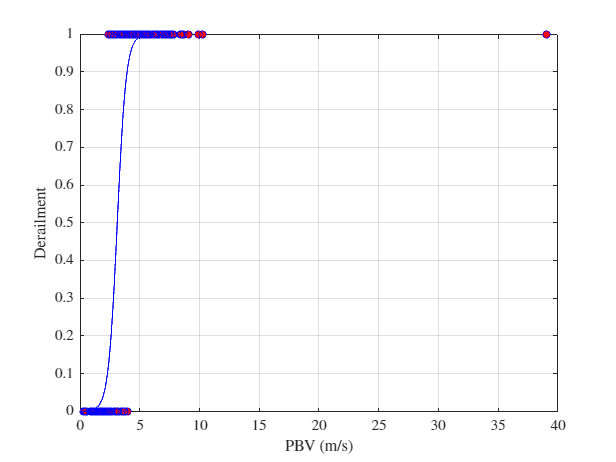

close
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
figure()
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'r.', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:6.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'bo', ...
    xnew, ynew, 'b-', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')

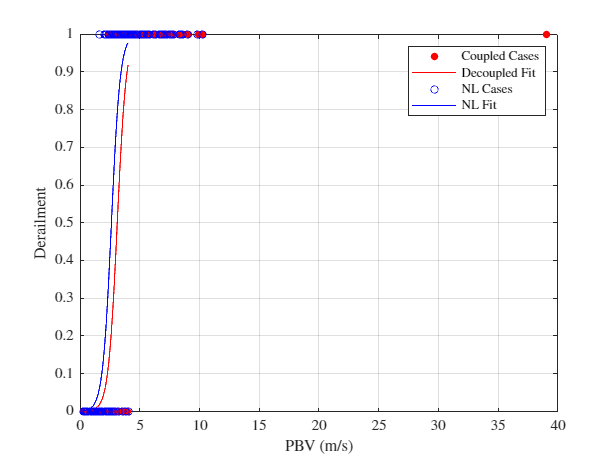

close
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
figure()
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'r.', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'bo', ...
    xnew, ynew, 'b-', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
legend('Coupled Cases', 'Decoupled Fit', 'NL Cases', 'NL Fit')

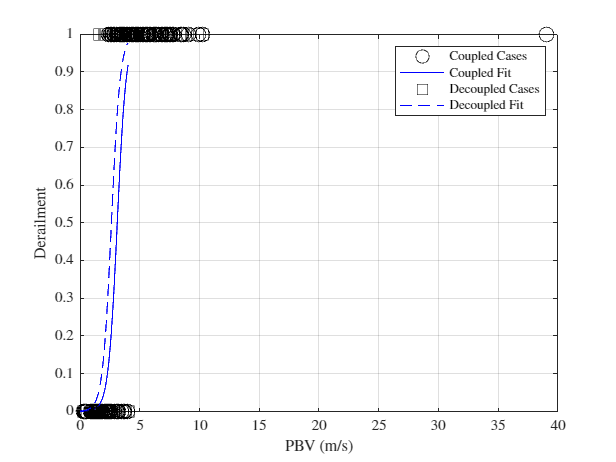

close
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
figure()
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'ko', ...
    xnew, ynew, 'b-', 'MarkerSize', 10.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'ks', ...
    xnew, ynew, 'b--', 'MarkerSize', 10.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
legend('Coupled Cases', 'Coupled Fit', 'Decoupled Cases', 'Decoupled Fit')

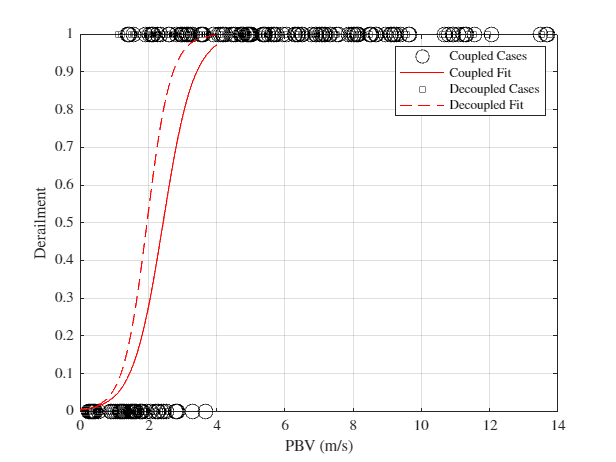

close
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
figure()
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'ko', ...
    xnew, ynew, 'r-', 'MarkerSize', 10.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'ks', ...
    xnew, ynew, 'r--', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
legend('Coupled Cases', 'Coupled Fit', 'Decoupled Cases', 'Decoupled Fit')

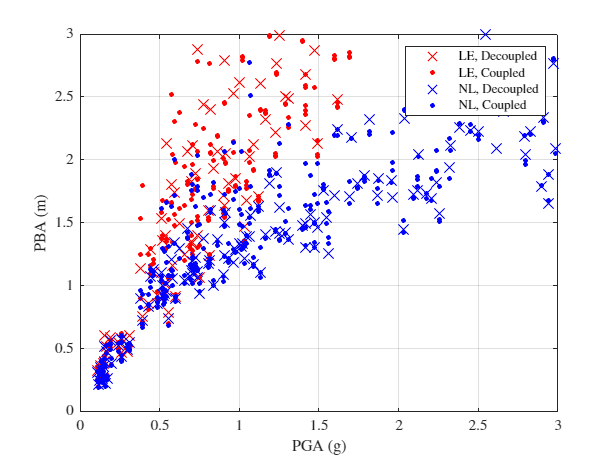

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

figure()
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBA (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

axis([0, 3, 0, 3])
grid on

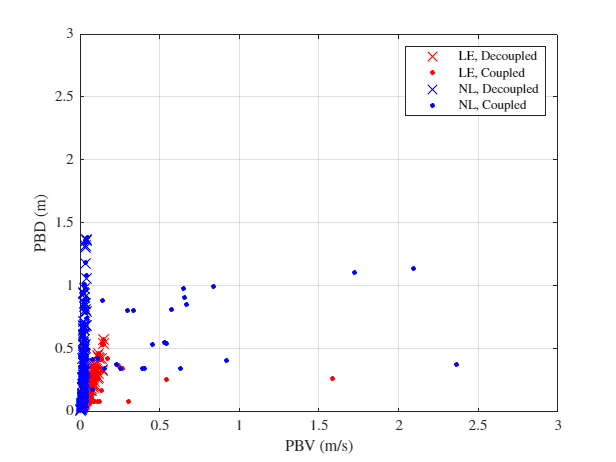

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

figure()
plot(SummTable(indices1,:).pba/981, SummTable(indices1,:).pbd, 'rx', ...
     SummTable(indices2,:).pba/981, SummTable(indices2,:).pbd, 'r.', ...
     SummTable(indices3,:).pba/981, SummTable(indices3,:).pbd, 'bx', ...
     SummTable(indices4,:).pba/981, SummTable(indices4,:).pbd, 'b.','MarkerSize', 10.0)

xlabel('PBV (m/s)'), ylabel('PBD (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

axis([0, 3, 0, 3])
grid on

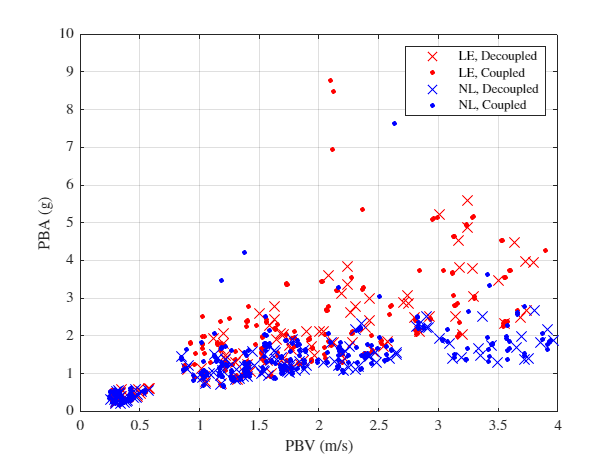

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

figure()
plot(SummTable(indices1,:).pbv, SummTable(indices1,:).pba/9.81, 'rx', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).pba/9.81, 'r.', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).pba/9.81, 'bx', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).pba/9.81, 'b.','MarkerSize', 10.0)

xlabel('PBV (m/s)'), ylabel('PBA (g)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

axis([0, 4, 0, 10])
grid on

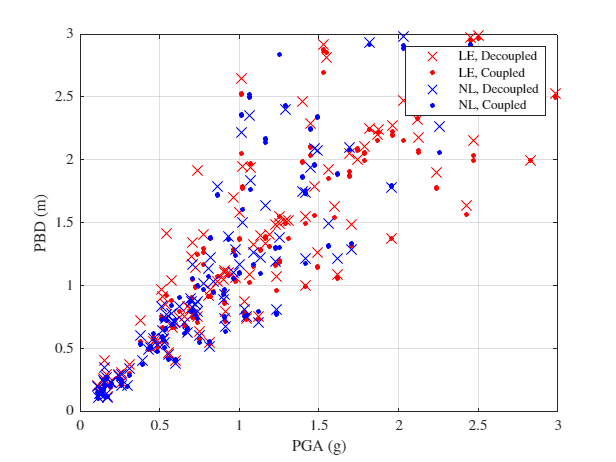

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

figure()
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pbd / 6 * 100, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pbd / 6 * 100, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pbd / 6 * 100, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pbd / 6 * 100, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBD (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')


axis([0, 3, 0, 3])
grid on

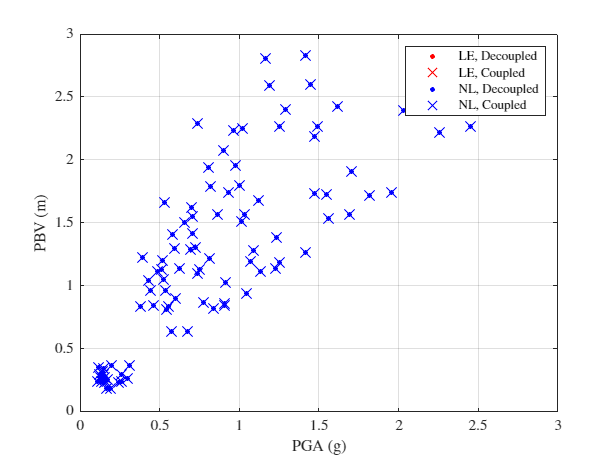

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

figure()
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pgv, 'r.', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pgv, 'rx', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pgv, 'b.', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pgv, 'bx','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBV (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')


axis([0, 3, 0, 3])
grid on

% close
% indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0));  % Linear Elastic, Decoupled
% indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0));  % Nonlinear, Decoupled
% indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0));  % Linear Elastic, Coupled
% indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0));  % Nonlinear, Coupled
% plot(SummTable(indices1,:).pbd/9.81, SummTable(indices1,:).pcha/9.81, 'r.', ...
%      SummTable(indices2,:).pbd/9.81, SummTable(indices2,:).pcha/9.81, 'b.', ...
%      SummTable(indices3,:).pbd/9.81, SummTable(indices3,:).pcha/9.81, 'rx', ...
%      SummTable(indices4,:).pbd/9.81, SummTable(indices4,:).pcha/9.81, 'bx','MarkerSize', 10.0)
% grid on

% close
% indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
% indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
% indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
% indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled
%plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rs', ...
%     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'ro', ...
%     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'ks', ...
%     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'ko','MarkerSize', 5.0), grid

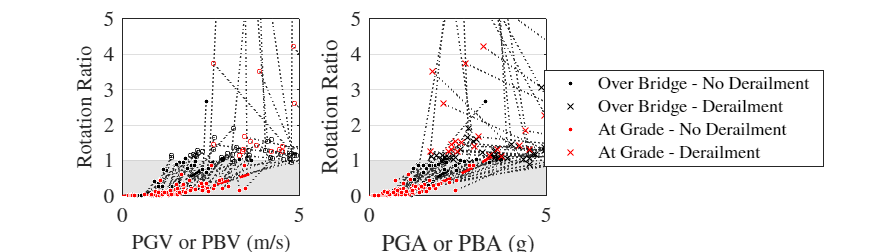

cfac = 1.0;

fig = figure();
subplot(1, 3, 1)
markersize = 3;

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.cf == 1.0));  % At grade, No derail
indices4 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 1.0).*(SummTable_AG.cf == 1.0));  % At grade, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.purot/peakrot < 5.0).*(SummTable_AG.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pbv, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_AG(idx_8,:).pgv, SummTable_AG(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pbv, SummTable_AG(indices6(i),:).pgv], ...
        [SummTable_OB(indices5(i),:).purot, SummTable_AG(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
plot(0:0.01:2.60, pfit1(0:0.01:2.60)/peakrot, 'k--', ...
     0:0.01:3.59, pfit2(0:0.01:3.59)/peakrot, 'r--', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pbv, SummTable_OB(indices1,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pbv, SummTable_OB(indices2,:).purot/peakrot, 'ko', 'MarkerSize', markersize)
plot(SummTable_AG(indices3,:).pgv, SummTable_AG(indices3,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_AG(indices4,:).pgv, SummTable_AG(indices4,:).purot/peakrot, 'ro', 'MarkerSize', markersize)

axis([0 5.0 0 5.0]), grid, axis square
%legend('OB - No Derailment', 'OB - Derailment','AG - No Derailment', 'AG -Derailment', Location='northwest')
xlabel('PGV or PBV (m/s)'), ylabel('Rotation Ratio')


% Now, another plot
cfac = 1.0;
subplot(1,3,2)

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.cf == 1.0));  % At grade, No derail
indices4 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 1.0).*(SummTable_AG.cf == 1.0));  % At grade, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.purot/peakrot < 5.0).*(SummTable_AG.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pba/9.81, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_AG(idx_8,:).pga/9.81, SummTable_AG(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pba, SummTable_AG(indices6(i),:).pga]/9.81, ...
        [SummTable_OB(indices5(i),:).purot, SummTable_AG(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
semilogy(0:0.01:2.57, pfit1(0:0.01:2.57)/peakrot, 'k--', ...
     0:0.01:3.54, pfit2(0:0.01:3.54)/peakrot, 'r--', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pba/9.81, SummTable_OB(indices1,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pba/9.81, SummTable_OB(indices2,:).purot/peakrot, 'kx', 'MarkerSize', 2*markersize)
plot(SummTable_AG(indices3,:).pga/9.81, SummTable_AG(indices3,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_AG(indices4,:).pga/9.81, SummTable_AG(indices4,:).purot/peakrot, 'rx', 'MarkerSize', 2*markersize)
xlabel('PGA or PBA (g)'), ylabel('Rotation Ratio')
axis([0 5.0 0 5.0]), grid, axis square

lgd = legend('Over Bridge - No Derailment', 'Over Bridge - Derailment','At Grade - No Derailment', 'At Grade - Derailment');
lgd.Position = lgd.Position + [0.40, 0.0, 0.0, 0.0];
fig.Position = [0 0 1400 400];

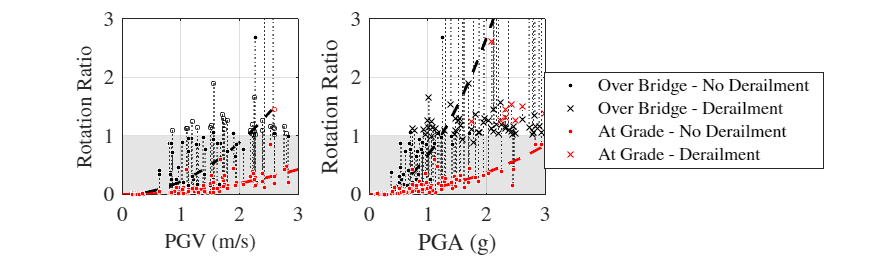

% 
cfac = 1.0;

fig = figure();
subplot(1, 3, 1)
markersize = 3;

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.cf == 1.0));  % At grade, No derail
indices4 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 1.0).*(SummTable_AG.cf == 1.0));  % At grade, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.purot/peakrot < 5.0).*(SummTable_AG.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pgv, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_AG(idx_8,:).pgv, SummTable_AG(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pgv, SummTable_AG(indices6(i),:).pgv], ...
        [SummTable_OB(indices5(i),:).purot, SummTable_AG(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
plot(0:0.01:2.55, pfit1(0:0.01:2.55)/peakrot, 'k--', ...
     0:0.01:3.80, pfit2(0:0.01:3.80)/peakrot, 'r--', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pgv, SummTable_OB(indices1,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pgv, SummTable_OB(indices2,:).purot/peakrot, 'ko', 'MarkerSize', markersize)
plot(SummTable_AG(indices3,:).pgv, SummTable_AG(indices3,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_AG(indices4,:).pgv, SummTable_AG(indices4,:).purot/peakrot, 'ro', 'MarkerSize', markersize)

axis([0 3.0 0 3.0]), grid, axis square
%legend('OB - No Derailment', 'OB - Derailment','AG - No Derailment', 'AG -Derailment', Location='northwest')
xlabel('PGV (m/s)'), ylabel('Rotation Ratio')


% Now, another plot
cfac = 1.0;
subplot(1,3,2)

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.cf == 1.0));  % At grade, No derail
indices4 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 1.0).*(SummTable_AG.cf == 1.0));  % At grade, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_AG.spd < 1.0).*(SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.purot/peakrot < 5.0).*(SummTable_AG.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pga/9.81, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_AG(idx_8,:).pga/9.81, SummTable_AG(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pga, SummTable_AG(indices6(i),:).pga]/9.81, ...
        [SummTable_OB(indices5(i),:).purot, SummTable_AG(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
semilogy(0:0.01:2.55, pfit1(0:0.01:2.55)/peakrot, 'k--', ...
     0:0.01:3.80, pfit2(0:0.01:3.80)/peakrot, 'r--', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pga/9.81, SummTable_OB(indices1,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pga/9.81, SummTable_OB(indices2,:).purot/peakrot, 'kx', 'MarkerSize', 2*markersize)
plot(SummTable_AG(indices3,:).pga/9.81, SummTable_AG(indices3,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_AG(indices4,:).pga/9.81, SummTable_AG(indices4,:).purot/peakrot, 'rx', 'MarkerSize', 2*markersize)
xlabel('PGA (g)'), ylabel('Rotation Ratio')
axis([0 3.0 0 3.0]), grid, axis square

lgd = legend('Over Bridge - No Derailment', 'Over Bridge - Derailment','At Grade - No Derailment', 'At Grade - Derailment');
lgd.Position = lgd.Position + [0.40, 0.0, 0.0, 0.0];
fig.Position = [0 0 1200 350];

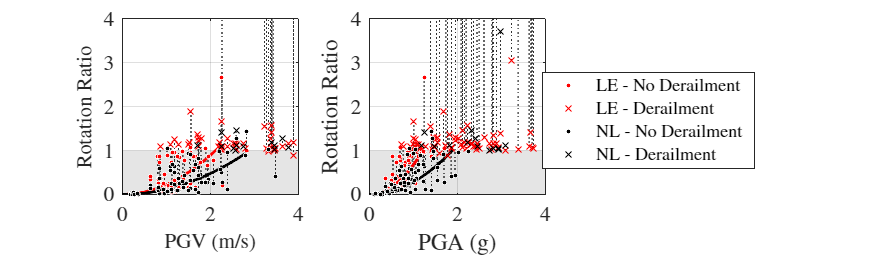

% 
cfac = 1.0;

fig = figure();
subplot(1, 3, 1)
markersize = 3;

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == 1.0));   % Over Bridge, Coupled, Linear, No derail
indices4 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == 1.0));   % Over Bridge, Coupled, Linear, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pgv, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_OB(idx_8,:).pgv, SummTable_OB(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pgv, SummTable_OB(indices6(i),:).pgv], ...
        [SummTable_OB(indices5(i),:).purot, SummTable_OB(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
plot(0:0.01:2.15, pfit1(0:0.01:2.15)/peakrot, 'r-', ...
     0:0.01:2.80, pfit2(0:0.01:2.80)/peakrot, 'k-', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pgv, SummTable_OB(indices1,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pgv, SummTable_OB(indices2,:).purot/peakrot, 'rx', 'MarkerSize', 2*markersize)
plot(SummTable_OB(indices3,:).pgv, SummTable_OB(indices3,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices4,:).pgv, SummTable_OB(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 2*markersize)

axis([0 4.0 0 4.0]), grid, axis square
%legend('OB - No Derailment', 'OB - Derailment','AG - No Derailment', 'AG -Derailment', Location='northwest')
xlabel('PGV (m/s)'), ylabel('Rotation Ratio')


% Now, another plot
cfac = 1.0;
subplot(1,3,2)

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == 1.0));  % At grade, No derail
indices4 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == 1.0));  % At grade, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pga/9.81, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_OB(idx_8,:).pga/9.81, SummTable_OB(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pga, SummTable_OB(indices6(i),:).pga]/9.81, ...
        [SummTable_OB(indices5(i),:).purot, SummTable_OB(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
semilogy(0:0.01:1.20, pfit1(0:0.01:1.20)/peakrot, 'r-', ...
     0:0.01:1.9, pfit2(0:0.01:1.9)/peakrot, 'k-', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pga/9.81, SummTable_OB(indices1,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pga/9.81, SummTable_OB(indices2,:).purot/peakrot, 'rx', 'MarkerSize', 2*markersize)
plot(SummTable_OB(indices3,:).pga/9.81, SummTable_OB(indices3,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices4,:).pga/9.81, SummTable_OB(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 2*markersize)
xlabel('PGA (g)'), ylabel('Rotation Ratio')
axis([0 4.0 0 4.0]), grid, axis square

lgd = legend('LE - No Derailment', 'LE - Derailment','NL - No Derailment', 'NL - Derailment');
lgd.Position = lgd.Position + [0.30, 0.0, 0.0, 0.0];
fig.Position = [0 0 1200 350];

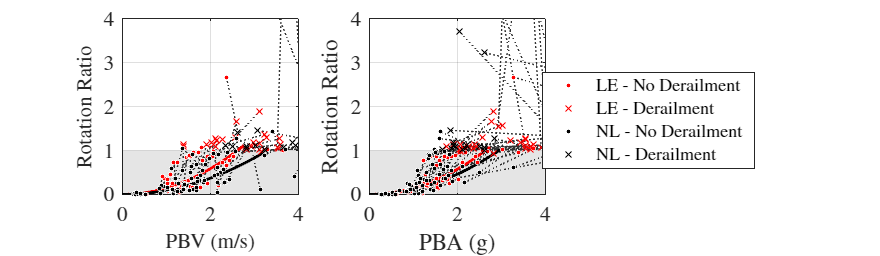

% 
cfac = 1.0;

fig = figure();
subplot(1, 3, 1)
markersize = 3;

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == 1.0));   % Over Bridge, Coupled, Linear, No derail
indices4 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == 1.0));   % Over Bridge, Coupled, Linear, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pbv, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_OB(idx_8,:).pbv, SummTable_OB(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pbv, SummTable_OB(indices6(i),:).pbv], ...
        [SummTable_OB(indices5(i),:).purot, SummTable_OB(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
plot(0:0.01:2.75, pfit1(0:0.01:2.75)/peakrot, 'r-', ...
     0:0.01:3.20, pfit2(0:0.01:3.20)/peakrot, 'k-', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pbv, SummTable_OB(indices1,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pbv, SummTable_OB(indices2,:).purot/peakrot, 'rx', 'MarkerSize', 2*markersize)
plot(SummTable_OB(indices3,:).pbv, SummTable_OB(indices3,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices4,:).pbv, SummTable_OB(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 2*markersize)

axis([0 4.0 0 4.0]), grid, axis square
%legend('OB - No Derailment', 'OB - Derailment','AG - No Derailment', 'AG -Derailment', Location='northwest')
xlabel('PBV (m/s)'), ylabel('Rotation Ratio')


% Now, another plot
cfac = 1.0;
subplot(1,3,2)

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == 1.0));  % At grade, No derail
indices4 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == 1.0));  % At grade, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pba/9.81, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_OB(idx_8,:).pba/9.81, SummTable_OB(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pba, SummTable_OB(indices6(i),:).pba]/9.81, ...
        [SummTable_OB(indices5(i),:).purot, SummTable_OB(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
semilogy(0:0.01:2.75, pfit1(0:0.01:2.75)/peakrot, 'r-', ...
         0:0.01:3.05, pfit2(0:0.01:3.05)/peakrot, 'k-', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pba/9.81, SummTable_OB(indices1,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pba/9.81, SummTable_OB(indices2,:).purot/peakrot, 'rx', 'MarkerSize', 2*markersize)
plot(SummTable_OB(indices3,:).pba/9.81, SummTable_OB(indices3,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices4,:).pba/9.81, SummTable_OB(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 2*markersize)
xlabel('PBA (g)'), ylabel('Rotation Ratio')
axis([0 4.0 0 4.0]), grid, axis square

lgd = legend('LE - No Derailment', 'LE - Derailment','NL - No Derailment', 'NL - Derailment');
lgd.Position = lgd.Position + [0.30, 0.0, 0.0, 0.0];
fig.Position = [0 0 1200 350];

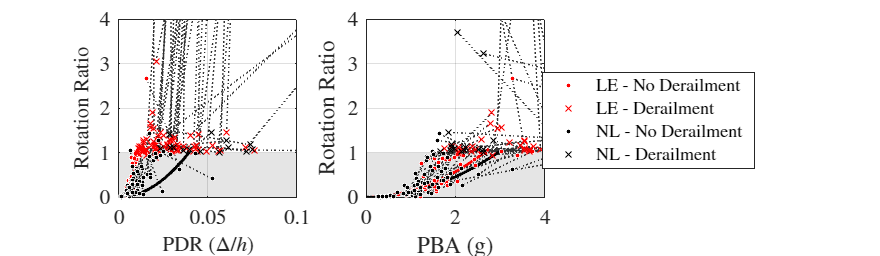

% 
cfac = 1.0;

fig = figure();
subplot(1, 3, 1)
markersize = 3;

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == 1.0));   % Over Bridge, Coupled, Linear, No derail
indices4 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == 1.0));   % Over Bridge, Coupled, Linear, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pbd/6, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_OB(idx_8,:).pbd/6, SummTable_OB(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pbd/6, SummTable_OB(indices6(i),:).pbd/6], ...
        [SummTable_OB(indices5(i),:).purot, SummTable_OB(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
plot(0:0.001:0.012, pfit1(0:0.001:0.012)/peakrot, 'r-', ...
     0:0.001:0.04, pfit2(0:0.001:0.04)/peakrot, 'k-', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pbd/6, SummTable_OB(indices1,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pbd/6, SummTable_OB(indices2,:).purot/peakrot, 'rx', 'MarkerSize', 2*markersize)
plot(SummTable_OB(indices3,:).pbd/6, SummTable_OB(indices3,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices4,:).pbd/6, SummTable_OB(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 2*markersize)

axis([0 0.1 0 4.0]), grid, axis square
%legend('OB - No Derailment', 'OB - Derailment','AG - No Derailment', 'AG -Derailment', Location='northwest')
xlabel('PDR ($\Delta/h$)'), ylabel('Rotation Ratio')


% Now, another plot
cfac = 1.0;
subplot(1,3,2)

indices1 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == 1.0));  % At grade, No derail
indices4 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == 1.0));  % At grade, Derail

indices5 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.cf == 1.0));

peakrot = 0.836; % Degrees
idx_7 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == cfac));
idx_8 = find((SummTable_OB.spd < 1.0).*(SummTable_OB.bridgemodel == 1.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.purot/peakrot < 5.0).*(SummTable_OB.cf == 1.0));

pfit1 = fit(SummTable_OB(idx_7,:).pba/9.81, SummTable_OB(idx_7,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable_OB(idx_8,:).pba/9.81, SummTable_OB(idx_8,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pba, SummTable_OB(indices6(i),:).pba]/9.81, ...
        [SummTable_OB(indices5(i),:).purot, SummTable_OB(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(14, 'points')
semilogy(0:0.01:2.75, pfit1(0:0.01:2.75)/peakrot, 'r-', ...
         0:0.01:3.05, pfit2(0:0.01:3.05)/peakrot, 'k-', 'LineWidth', 2.0, 'HandleVisibility', 'off');

plot(SummTable_OB(indices1,:).pba/9.81, SummTable_OB(indices1,:).purot/peakrot, 'ro', 'MarkerSize', markersize, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices2,:).pba/9.81, SummTable_OB(indices2,:).purot/peakrot, 'rx', 'MarkerSize', 2*markersize)
plot(SummTable_OB(indices3,:).pba/9.81, SummTable_OB(indices3,:).purot/peakrot, 'ko', 'MarkerSize', markersize, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','w')
plot(SummTable_OB(indices4,:).pba/9.81, SummTable_OB(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 2*markersize)
xlabel('PBA (g)'), ylabel('Rotation Ratio')
axis([0 4.0 0 4.0]), grid, axis square

lgd = legend('LE - No Derailment', 'LE - Derailment','NL - No Derailment', 'NL - Derailment');
lgd.Position = lgd.Position + [0.30, 0.0, 0.0, 0.0];
fig.Position = [0 0 1200 350];